# Heart Attack Project Code

## Initializing Data

h_data = readtable("processedcleveland_ind.csv"); 

% Normalize
h_data{:,[1, 6, 7, 10, 12]} = normalize(h_data{:,[1, 6, 7, 10, 12]});

% Total for K Fold
X_total = h_data{:,1:size((h_data),2)-1};
X_total = [ones(size(X_total,1),1), X_total];
y_total = h_data{:,size((h_data),2)};

% Train Test Partition
seed = 191;
rng(seed); % For reproducibility of the partition
c = cvpartition(h_data.output,"Holdout",0.20);

trainingIndices = training(c); % Indices for the training set
testIndices     = test(c); % Indices for the test set

% Tabular Data
h_dataTrain = h_data(trainingIndices,:);
h_dataTest  = h_data(testIndices,:);

% Feature Matricies
X_train = h_dataTrain{:,1:size((h_dataTrain),2)-1};
X_test  = h_dataTest{:,1:size((h_dataTest),2)-1};

% Y values
y_train = h_dataTrain{:,size((h_dataTrain),2)};
y_test  = h_dataTest{:,size((h_dataTest),2)};

% Add Bias
X_train = [ones(size(X_train,1),1), X_train];
X_test  = [ones(size(X_test,1),1), X_test];

## Logistic Regression (LR) Gradient Descent

% Function Calls
[m,n] = size(h_data);

% Initialize fitting parameters
% n has 20 columns, the output is added to the size but this is fine cause we need to add the bias term anyway
initial_theta = zeros(n,1); 

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, cost] = ...
    fminunc(@(t)(costFunctionLR(t, X_train, y_train)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.326120



fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 -1.433286 
 -0.194872 
 1.523050 
 -2.933011 
 -1.105905 
 -1.792139 
 0.574912 
 0.250732 
 -0.955491 
 0.553241 
 -0.377555 
 0.816567 
 0.385334 
 -1.307274 
 -0.446034 
 1.872763 
 3.822230 
 2.273475 
 -0.586793 
 1.246118 


% Accuracy Checking

p_train = predictLog(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 86.974790


p_test = predictLog(theta, X_test);
test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

Test Accuracy: 91.525424


## Regularized Logistic Regression (RLR) Gradient Descent

lambda_values = [0,0.1,1,3,4,5,10,20,999];
K = 5; % number of folds
results = zeros(length(lambda_values), 2);

% Create K-fold partition of training set
cv = cvpartition(y_total, 'KFold', K);

for i = 1:length(lambda_values)
    lambda = lambda_values(i);
    fold_accuracies = zeros(K,1);

    for fold_i = 1:K
        % Get training and validation indices for fold
        trainIdx = training(cv, fold_i);
        valIdx   = test(cv, fold_i);

        % Partitioning
        X_train_fold = X_total(trainIdx,:);
        y_train_fold = y_total(trainIdx);
        X_val_fold   = X_total(valIdx,:);
        y_val_fold   = y_total(valIdx);

        % Initialize theta for optimization
        initial_theta = zeros(size(X_train_fold,2), 1);

        % Set optimization options
        options    = optimset('GradObj', 'on', 'MaxIter', 400);

        % Optimize for this fold
        [theta, ~] = fminunc(@(t)(costFunctionRLR(t, X_train_fold, y_train_fold, lambda)), ...
                             initial_theta, options);

        % Evaluate on validation fold
        p_val = predictLog(theta, X_val_fold);
        fold_accuracies(fold_i) = mean(double(p_val == y_val_fold)) * 100;
    end

    % Compute the mean accuracy across all folds for this lambda
    cv_accuracy = mean(fold_accuracies);

    % Store the results
    results(i, :) = [lambda, cv_accuracy];
end


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

results

results =          0   82.1525
    0.1000   83.1638
    1.0000   83.5085
    3.0000   83.5028
    4.0000   84.8531
    5.0000   84.1751
   10.0000   82.4915
   20.0000   80.8079
  999.0000   63.6384


% Initialize fitting parameters
% n has 20 columns, the output is added to the size but this is fine cause we need to add the bias term anyway
initial_theta = zeros(n, 1);

% Set regularization parameter lambda
lambda  = 3;

% Set Options
options = optimset('GradObj', 'on', 'MaxIter', 400);

% Optimize
[theta, J, exit_flag] = ...
        fminunc(@(t)(costFunctionRLR(t, X_train, y_train, lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.326120


fprintf('Thetas\n');

Thetas


fprintf(' %f \n', theta); 

 -1.028597 
 0.042293 
 0.697046 
 -0.818959 
 -0.404428 
 -0.862001 
 0.235130 
 0.218358 
 -0.272231 
 0.272798 
 -0.405724 
 0.598475 
 0.442454 
 -0.540703 
 -0.171017 
 0.709773 
 1.173698 
 0.584739 
 0.035764 
 1.029922 


% Accuracy Checking

p_train = predictLog(theta, X_train);
train_accuracy = mean(double(p_train == y_train)) * 100;
fprintf('Training Accuracy: %f\n', train_accuracy);

Training Accuracy: 86.554622


% p_cv = predictLog(theta, X_cv);
% cv_accuracy = mean(double(p_cv == y_cv)) * 100;
% fprintf('Cross Validation Accuracy: %f\n', cv_accuracy);
p_test = predictRLR(theta, X_test);

Unrecognized function or variable 'predictRLR'.

test_accuracy = mean(double(p_test == y_test)) * 100;
fprintf('Test Accuracy: %f\n', test_accuracy);

## Logistic Regression (LR) Cost Function

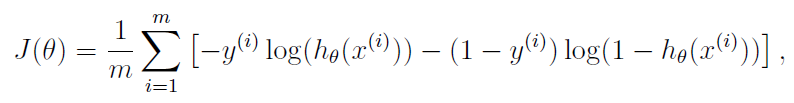

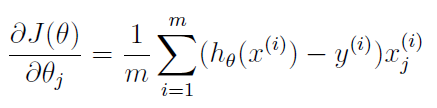

%=====================================================================================================%
function [J, grad] = costFunctionLR(theta, X, y)

m    = length(y);

h    = sigmoid(X*theta);

J    = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));
grad = (1/m) * (X' * (h - y));

end
%=====================================================================================================%

## Regularized Logistic Regression (RLR) Cost Function

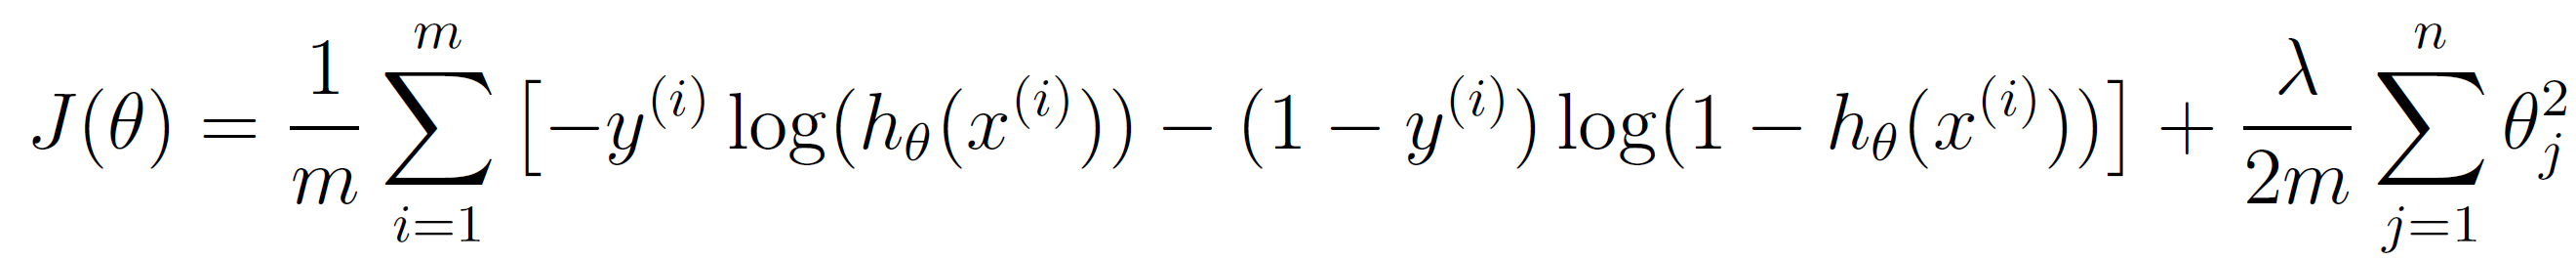

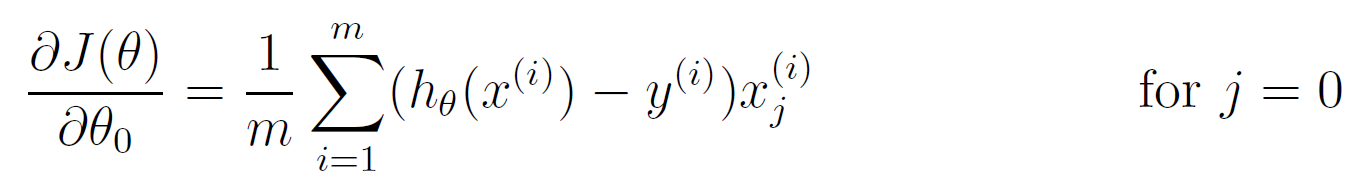

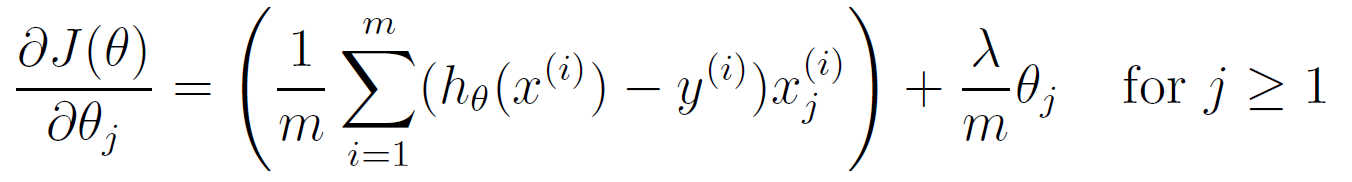

%=====================================================================================================%
function [J, grad] = costFunctionRLR(theta, X, y, lambda)

m = length(y); % number of training examples

h = sigmoid(X*theta);

J = (1/m*sum(-y.*log(h)-(1-y).*log(1-h)));
J = J + (lambda/(2*m)) * sum(theta(2:end).^2);

grad        = (1/m) * (X' * (h - y));
grad(2:end) = grad(2:end) + (lambda/m) * theta(2:end);

end

%=====================================================================================================%

## Sigmoid Function

%=====================================================================================================%
function g = sigmoid(z)

g = zeros(size(z));
g = 1./(1+exp(-z)); %g = 1./(1+e.^(-z))

end
%=====================================================================================================%

## Predict Function Logistic Regression

%=====================================================================================================%
function p = predictLog(theta, X)

m = size(X,1);
p = zeros(m, 1);

h = sigmoid(X*theta);
p(h>=0.5) = 1;

end
%=====================================================================================================%

## Plot Histogram

%=====================================================================================================%
function plotHistogram(data, plotTitle)
    % plotHistogram creates a histogram for the input data array with a title.
    % Inputs:
    %   - data: Array of numeric data to be visualized in the histogram
    %   - plotTitle: String for the title of the plot

    % Create the histogram
    histogram(data, 'NumBins', 30, 'FaceColor', 'blue', 'EdgeColor', 'black');

    % Customize the appearance
    xlabel('Data Values');
    ylabel('Frequency');
    title(plotTitle);
    grid on;
end
%=====================================================================================================%